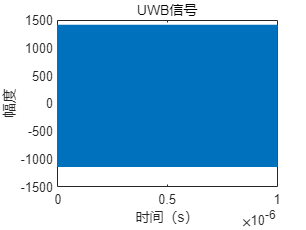

% 信道模型

channel_delay = [0, 1e-9, 2e-9]; % 通道延迟
channel_gain = [0, -3, -6]; % 通道增益（损耗）
h = zeros(num_antennas, length(tx_signal));

函数或变量 'num_antennas' 无法识别。

for i = 1:num_antennas
    % 生成不同通道延迟和增益的信道
    h(i, :) = sum(repmat(channel_gain, num_packets, 1) .* exp(1j*2*pi*fc*repmat(channel_delay, num_packets, 1)), 2);
end

% 接收端处理
rx_signal = zeros(num_antennas, num_packets*fs);
for i = 1:num_packets
    for j = 1:num_antennas
        % 信号通过信道
        rx_signal(j, (i-1)*fs+1:i*fs) = conv(tx_signal(j, (i-1)*fs+1:i*fs), h(j, :), 'same');
    end
end

% 估计CIR
estimated_cir = zeros(num_antennas, length(h));
for i = 1:num_antennas
    % 使用最小二乘法估计CIR
    estimated_cir(i, :) = lsqnonneg(tx_signal(i, :).', rx_signal(i, :).');
end

% 绘制结果
figure;
for i = 1:num_antennas
    subplot(num_antennas, 1, i);
    plot(estimated_cir(i, :));
    title(['Channel Impulse Response for Antenna ' num2str(i)]);
    xlabel('Sample Index');
    ylabel('Amplitude');
end
